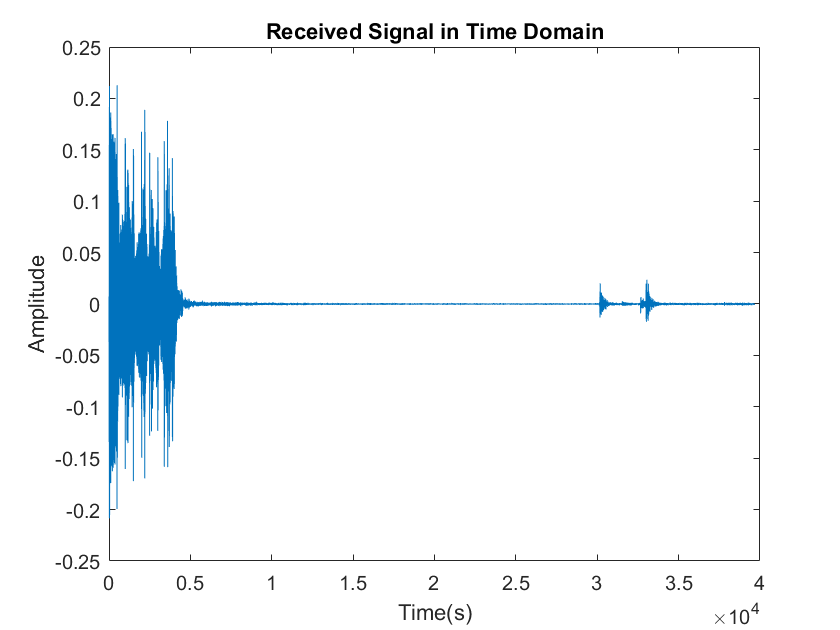

load short_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission

figure(1)
plot(y_t)
xlabel("Time(s)")
ylabel("Amplitude")
title("Received Signal in Time Domain")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
%%
%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(2)
f = (-length(y_t)/2:length(y_t)/2-1)*(Fs/length(y_t))

f = 	1.0e+03 *

   -4.0960   -4.0958   -4.0956   -4.0954   -4.0952   -4.0950   -4.0948   -4.0946   -4.0943   -4.0941   -4.0939   -4.0937   -4.0935   -4.0933   -4.0931   -4.0929   -4.0927   -4.0925   -4.0923   -4.0921   -4.0919   -4.0917   -4.0915   -4.0912   -4.0910   -4.0908   -4.0906   -4.0904   -4.0902   -4.0900   -4.0898   -4.0896   -4.0894   -4.0892   -4.0890   -4.0888   -4.0886   -4.0884   -4.0882   -4.0879   -4.0877   -4.0875   -4.0873   -4.0871   -4.0869   -4.0867   -4.0865   -4.0863   -4.0861   -4.0859


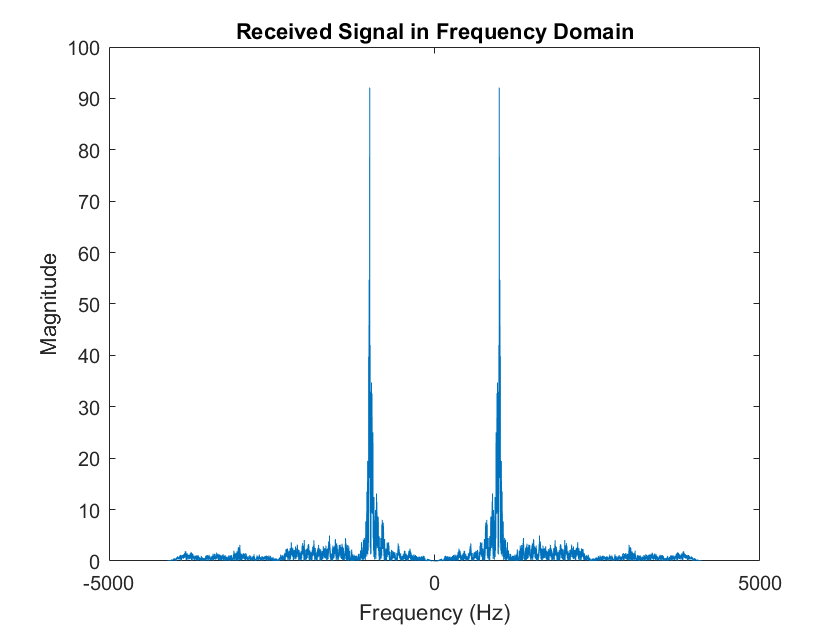

% Plot the unfiltered signal's frequencies
plot(f, fftshift(abs(fft(y_t))))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
title("Received Signal in Frequency Domain")

% Shift the signal back to zero in the frequency domain by multiplying by
% the cosine.
c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
y_c = y_t.*c;

figure(3)
f = (-length(y_c)/2:length(y_c)/2-1)*(Fs/length(y_c))

f = 	1.0e+03 *

   -4.0960   -4.0958   -4.0956   -4.0954   -4.0952   -4.0950   -4.0948   -4.0946   -4.0943   -4.0941   -4.0939   -4.0937   -4.0935   -4.0933   -4.0931   -4.0929   -4.0927   -4.0925   -4.0923   -4.0921   -4.0919   -4.0917   -4.0915   -4.0912   -4.0910   -4.0908   -4.0906   -4.0904   -4.0902   -4.0900   -4.0898   -4.0896   -4.0894   -4.0892   -4.0890   -4.0888   -4.0886   -4.0884   -4.0882   -4.0879   -4.0877   -4.0875   -4.0873   -4.0871   -4.0869   -4.0867   -4.0865   -4.0863   -4.0861   -4.0859


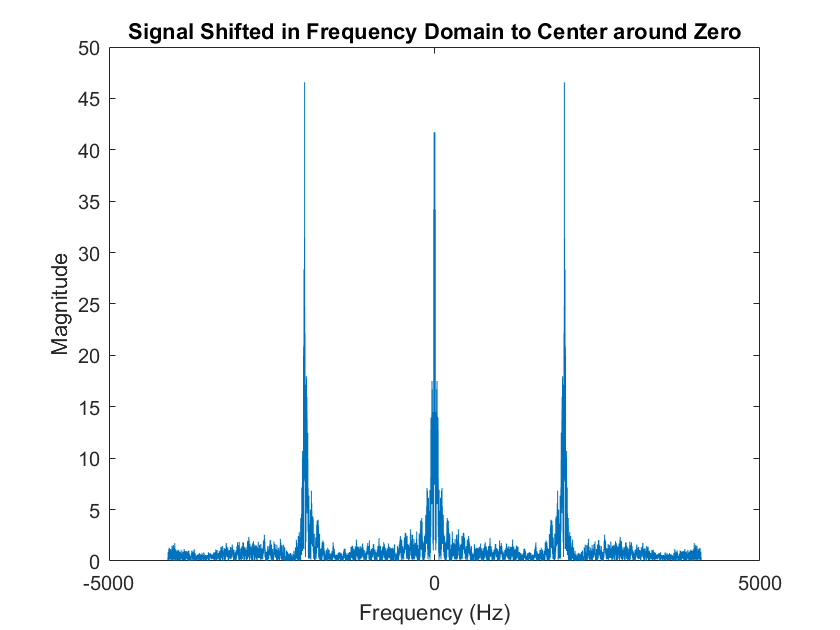

% Plot the unfiltered signal's frequencies
plot(f, fftshift(abs(fft(y_c))))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
title("Signal Shifted in Frequency Domain to Center around Zero")


% LPF

x_d = conv(y_c, (f_c/Fs*2)*sinc((f_c/Fs*2)*[-1000:1000]'))/2;

figure(4)
% Plot the filtered signal freqs
f = (-length(x_d)/2:length(x_d)/2-1)*(Fs/length(x_d))

f = 	1.0e+03 *

   -4.0960   -4.0958   -4.0956   -4.0954   -4.0952   -4.0950   -4.0948   -4.0946   -4.0944   -4.0942   -4.0940   -4.0938   -4.0936   -4.0934   -4.0932   -4.0931   -4.0929   -4.0927   -4.0925   -4.0923   -4.0921   -4.0919   -4.0917   -4.0915   -4.0913   -4.0911   -4.0909   -4.0907   -4.0905   -4.0903   -4.0901   -4.0899   -4.0897   -4.0895   -4.0893   -4.0891   -4.0889   -4.0887   -4.0885   -4.0883   -4.0881   -4.0879   -4.0877   -4.0875   -4.0873   -4.0872   -4.0870   -4.0868   -4.0866   -4.0864


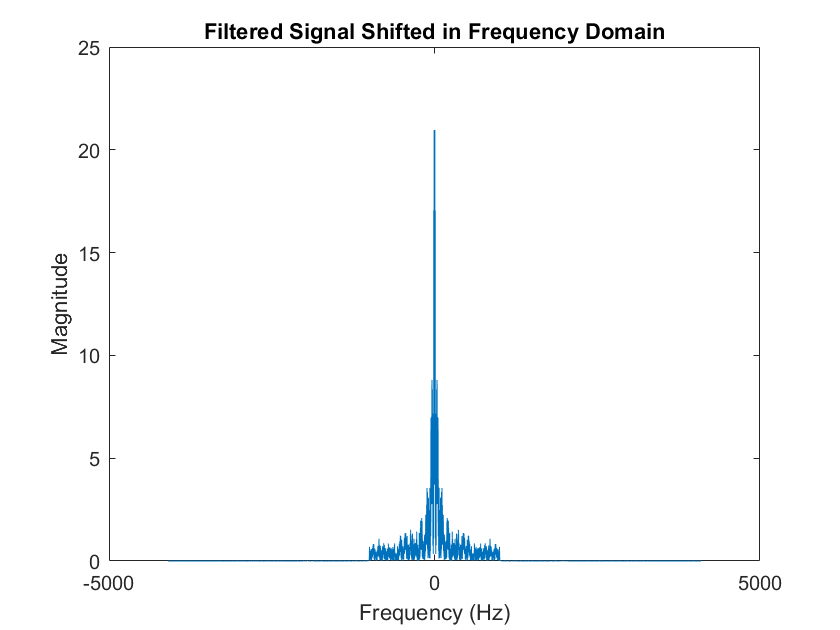

plot(f, fftshift(abs(fft(x_d))))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
title("Filtered Signal Shifted in Frequency Domain")

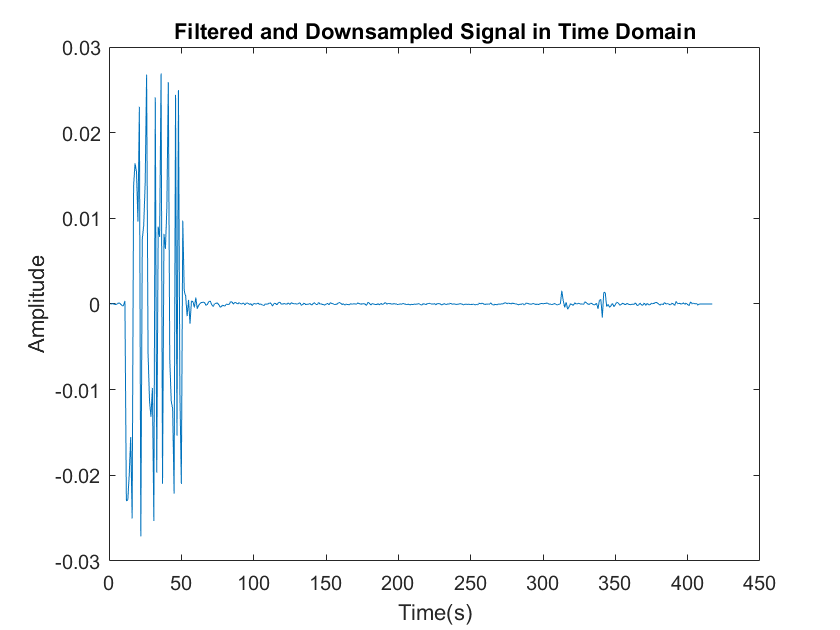

x_d_down = downsample(x_d, 100);

figure(5)
plot(x_d_down)
xlabel("Time(s)")
ylabel("Amplitude")
title("Filtered and Downsampled Signal in Time Domain")

above_thresh = find(abs(x_d_down) > 0.005);
start_point = above_thresh(1);
end_point = above_thresh(end);
x_d_cut = x_d_down(start_point:end_point);
%pad with 0s
%x_d_cut = [x_d_cut, zeros((8-mod(length(x_d_cut),8))*mod(length(x_d_cut)>0,8), 1)];

%figure(6)
%plot(x_d_cut>0)

% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits
BitsToString(x_d_cut>0)

ans = 'Hello'